# meas and mask manual binning

%% param
data_path ="E:\project\CACTI\experiment\real_data\data_cacti\mask_bin2_20210127\scene\data_d_hand_1_20210127_roi690-180_sz1024.mat";
bin_size = 2;

data_path = char(data_path);
save_path = [data_path(1:end-4) '_dataBinned' num2str(bin_size) '.mat'];


%% proc
% load
load(data_path)

% crop margin
maxsize = floor(size(meas)./bin_size).*bin_size;
meas = imcrop(meas,[1 1 maxsize-1]);

mask_num = size(mask,3);
for k=1:mask_num
    mask(:,:,k) = imcrop(mask(:,:,k),[1 1 maxsize-1]);
end

% binning
meas_binned = blkcolfun(meas,bin_size,@mean);
mask_binned = zeros([maxsize./bin_size, mask_num]);
for k=1:mask_num
    mask_binned(:,:,k) = blkcolfun(mask(:,:,k),bin_size,@mean);
end



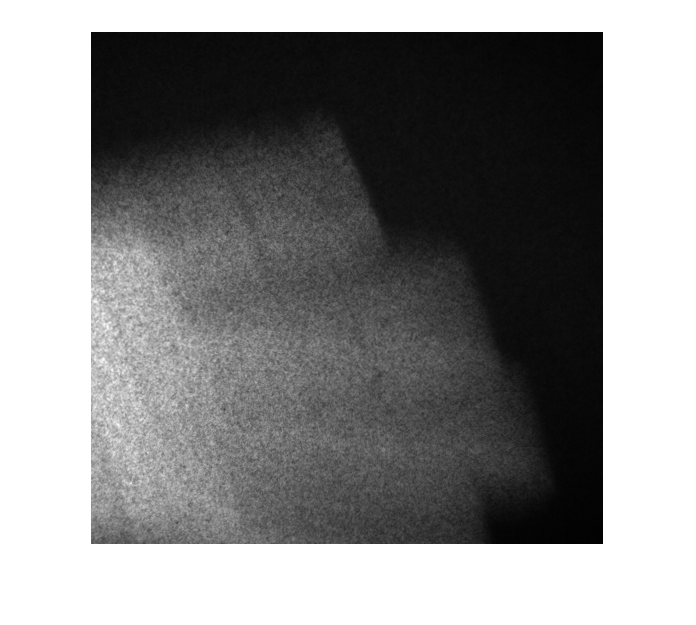

% show and save
meas = meas_binned;
mask = mask_binned;

figure, imshow(meas,[]);

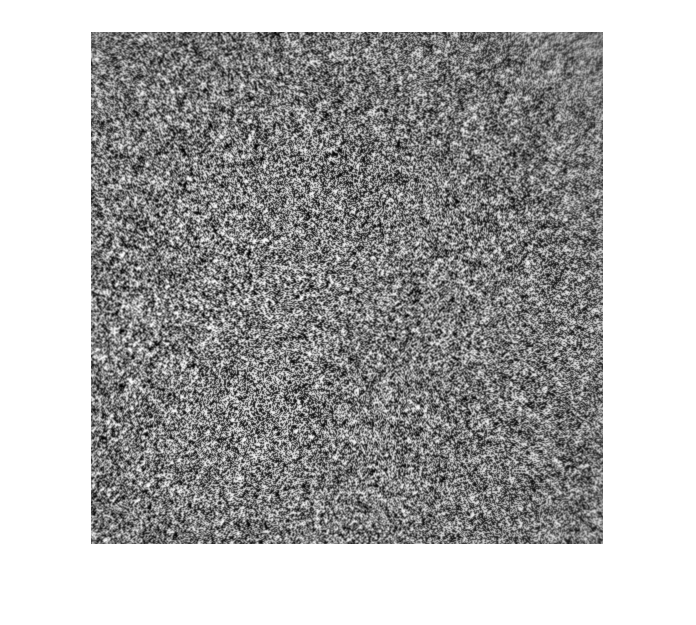

figure,imshow(mask(:,:,1),[])


save(save_path, 'mask', 'meas')